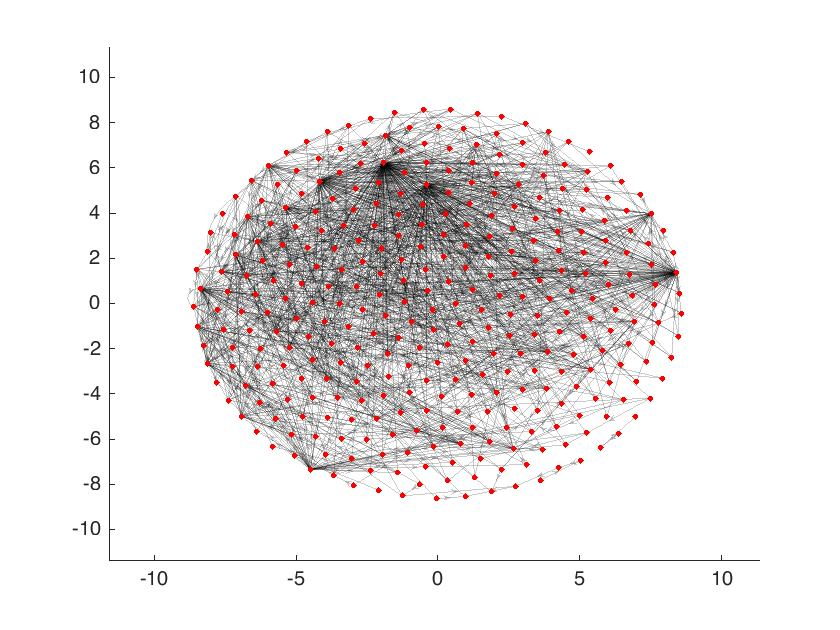

filename = "output_exempel.txt";
edges = importdata("get_edges_output.txt");

edges = split(edges);

start_nodes = edges(:,1);
end_nodes = edges(:,2);

G = digraph(start_nodes, end_nodes, 100);

hold on
h = plot(G, "MarkerSize", 2, "NodeColor", [1 0 0], "EdgeColor", [0 0 0]);

%Visa namn på noder -  'NodeLabel', G.Nodes.Name 
h.EdgeAlpha = 0.2;

%layout(h, "force3", "UseGravity",true);
layout(h, 'force', 'WeightEffect', "direct", "UseGravity","on");




%k = findnode(G, "Repository");
%highlight(h, k, 'NodeColor', 'g');

%layout(h, 'force3',"UseGravity", true);
%view(3);